# HRI Lab #3, Part a, SP2024 525.786: Human Robotics Interaction

## Introduction:

In this lab we will explore hand tracking tools. These tools, in combination with the bioinstrumentation inputs you've used previously, can be used for natural and intuitive Human Robotic Interaction. In this part of the lab, we'll be focusing on the Leap Motion Hand Sensor, an optical tracker capable of tracking hand position and finger angles on both hands simultaneously.

## Setup the MiniVIE environment

thisPath = cd;
cd('C:\GitHub\MiniVIE');
MiniVIE.configurePath;

[MiniVIE.m] Configured MiniVIE path at: C:\GitHub\minivie


cd(thisPath);

## LEAP Motion Controller

For information about how the LEAP motion works, check out this site:  [http://blog.leapmotion.com/hardware-to-software-how-does-the-leap-motion-controller-work/](http://blog.leapmotion.com/hardware-to-software-how-does-the-leap-motion-controller-work/)

Operating Principle: The LEAP motion contains infrared light emitters which bathe the workspace in IR light. Reflections of the IR light are picked up by two cameras. Software then converts the raw image into positions of the hand joints. Since the LEAP motion is optical (i.e., rather than relying on worn bend sensors like the CyberGlove), it is very easy to use but sensitive to occlusion, which may happen during certain positions of the hands relative to each other or during object manipulation when parts of the object may occlude the fingers.

Start LeapUdp.py, a Python application for streaming LEAP motion controller information to UDP,** by running StartLeapStream.bat in this  folder**

Visualize the data (run this in the command window, by highlighting and typing F9):

[PnetClass] Opened pnet socket #7 at local port: 14001; Default destination: port 45001 @ 127.0.0.1


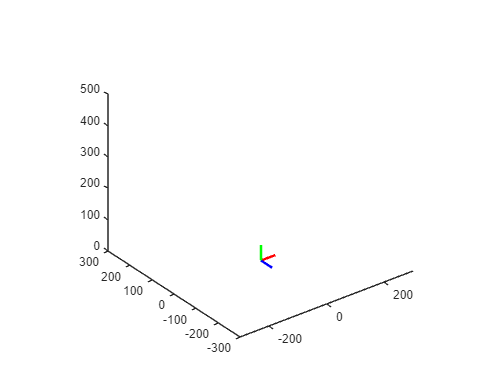

[PnetClass.m] Closed pnet socket #7 at local port: 14001


Inputs.LeapMotion.preview

Tasks/Questions:

 (a) If you wanted to compute one of the index finger angles, which nodes in the model would you need to use?

Index finger: Metacarpal bone, proximal bone, intermediate bone, distal bone

## Investigate a frame of raw data

% create a Leap Motion object
h = Inputs.LeapMotion;
h.initialize();

[PnetClass] Opened pnet socket #7 at local port: 14001; Default destination: port 45001 @ 127.0.0.1



% stream frames until the form is closed
% try to "catch" a frame by stopping the collection with at least one hand
% in the frame
StartStopForm([])
while StartStopForm
    drawnow;
    frame = h.getData();
    if isempty(frame)
        continue;
    end
    
    frame
end

h.close()

[PnetClass.m] Closed pnet socket #7 at local port: 14001


Tasks/Questions:

 (a) What information does the frame provide?  How are fingers represented?

The frame provides 3D coordinates of fingers and the direction the finger extends in towards the next joint (represented as nodes and segments in between the notes)

 Index finger, id: 551, length: 57.392670mm, width: 18.862999mm

      Bone: Metacarpal, start: , direction: 

      Bone: Proximal, start: (-275.392, 1093.51, -135.679), end: (-300.749, 1126.72, -132.188), direction: (0.604764, -0.792043, -0.0832395)

      Bone: Intermediate, start: (-300.749, 1126.72, -132.188), end: (-312.41, 1138.27, -115.244), direction: (0.494376, -0.4895, -0.718319)

      Bone: Distal, start: (-312.41, 1138.27, -115.244), end: (-318.05, 1142.15, -100.04), direction: (0.338219, -0.232763, -0.911828)

 (b) Write a code snippet that would take positions from the finger vertices in the frame structure and compute the index finger angle (**hint: look at "LinAlg.Anglebetween"**)

v1 =  [-20.7967, 123.791, 15.9917]'-[-86.6328, 126.508, 36.6356]';
v2 = [17.0918, 133.704, 8.80689]' - [-20.7967, 123.791, 15.9917]';
      

LinAlg.Anglebetween(v1,v2)

ans = 17.9338

## Now control the vMPL with the LEAP

Before running the code below, start the vMPL


% initialize the local ports and IP address
UdpLocalPort = 56789;
UdpDestinationPort = 25000; % 25100 = Left arm; 25000 = Right arm; 
UdpAddress = '127.0.0.1'; % IP address of the computer running vMPL

% create a PnetClass object to send commands to the arm
hArm = PnetClass(UdpLocalPort,UdpDestinationPort,UdpAddress);
hArm.initialize()

[PnetClass] Opened pnet socket #6 at local port: 56789; Default destination: port 25000 @ 127.0.0.1


ans = logical
   1



% create a Leap Motion object
h = Inputs.LeapMotion;
h.initialize();

[PnetClass] Opened pnet socket #7 at local port: 14001; Default destination: port 45001 @ 127.0.0.1



% we won't be focusing on the upper arm in this lab
upperArmAngles = zeros(1,7);

% Create a variable to store the 20 angles of the fingers, in radians
% 1: INDEX abduction/adduction
% 2: INDEX joint closest to the palm (MCP)
% 3: INDEX second joint (PIP)
% 4: INDEX furthest joint from the palm (DIP)
% 5: MIDDLE abduction/adduction
% 6: MIDDLE MCP
% 7: MIDDLE PIP
% 8: MIDDLE DIP
% 9: RING abduction/adduction
% 10: RING MCP
% 11: RING PIP
% 12: RING DIP
% 13: LITTLE abduction/adduction
% 14: LITTLE MCP
% 15: LITTLE PIP
% 16: LITTLE DIP
% 17: THUMB abduction/adduction
% 18: THUMB roll
% 19: THUMB MCP
% 20: THUMB DIP
fingerAngles = zeros(1,20);

StartStopForm([])
while StartStopForm
    
    % grab leap data
    frame = h.getData();
    if isempty(frame)
        continue;
    end
    
    % PUT YOUR CODE FOR MAPPING LEAP DATA TO JOINT ANGLE HERE
    % START WITH INDEX FINGER, THEN TRY OTHER FINGERS

    % construct the message, which is 27 floats
    % cast as unsigned 8-bit integers
    msg = typecast(single([upperArmAngles,fingerAngles]),'uint8');

    % send the data to the vMPL
    hArm.putData(msg);
    
    % update the StartStopForm visualization
    drawnow;
    
end


h.close();

[PnetClass.m] Closed pnet socket #7 at local port: 14001


hArm.close();

[PnetClass.m] Closed pnet socket #6 at local port: 56789


Tasks/Questions:

 (a) Did your method of calculating joint angle separate flexion/extension from abduction/adduction of the finger?  If not, how would you accomplish this?

 (b) Are there any "singularities" in your mapping function, where values might flip from one sign to the other?  Can you think of a scenario when this might happen?

## **Submitting This Lab**

Export this *.mlx file as Lab3a_Leap_##_<LastName1>_<LastName2>_<LastName3>_<LastName4>.pdf (## should be your computer number) and email to Lauren.Diaz@jhuapl.edu